Visualize data

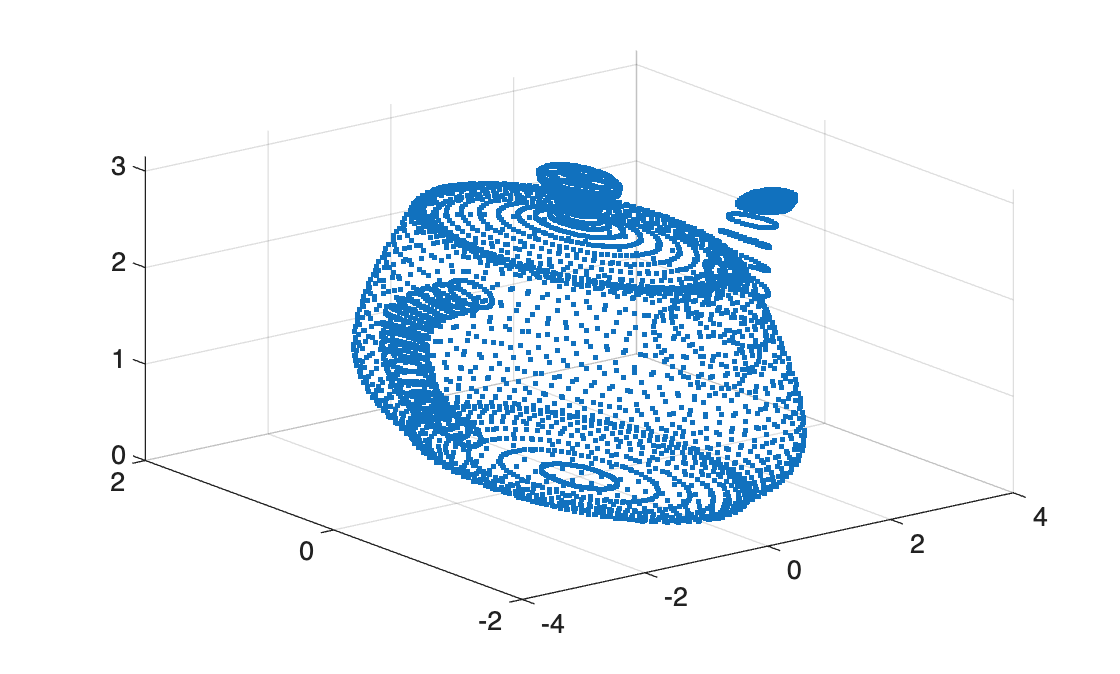

clear variables; close all; clc;
load('teapot.mat');
scatter3(M(1,:),M(2,:),M(3,:),'.')

Orthogonal projection

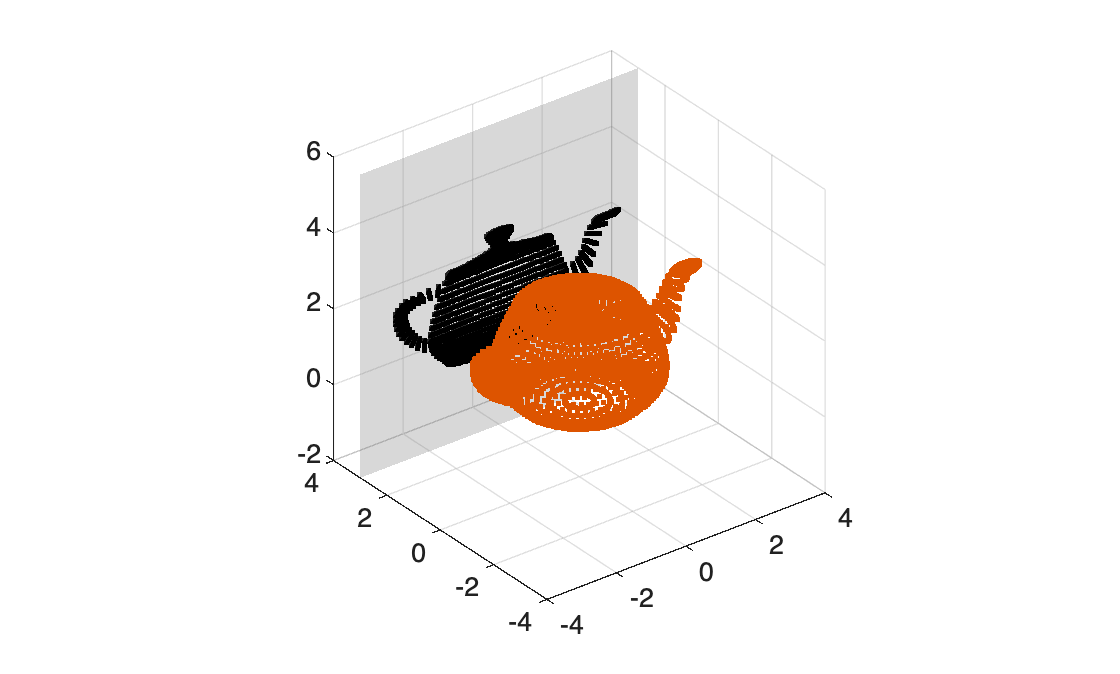

clear variables; close all; clc;
load('teapot.mat');
V = [1 0; 0 0; 0 1];
P = V*V';
n = null(V');
PM = P*M - 3*n;
constantplane(n,-3)
hold on
scatter3(M(1,:),M(2,:),M(3,:),'.')
scatter3(PM(1,:),PM(2,:),PM(3,:),'k.')
axis equal, axis([-4,4,-4,4,-2,6])
hold off

Oblique projection

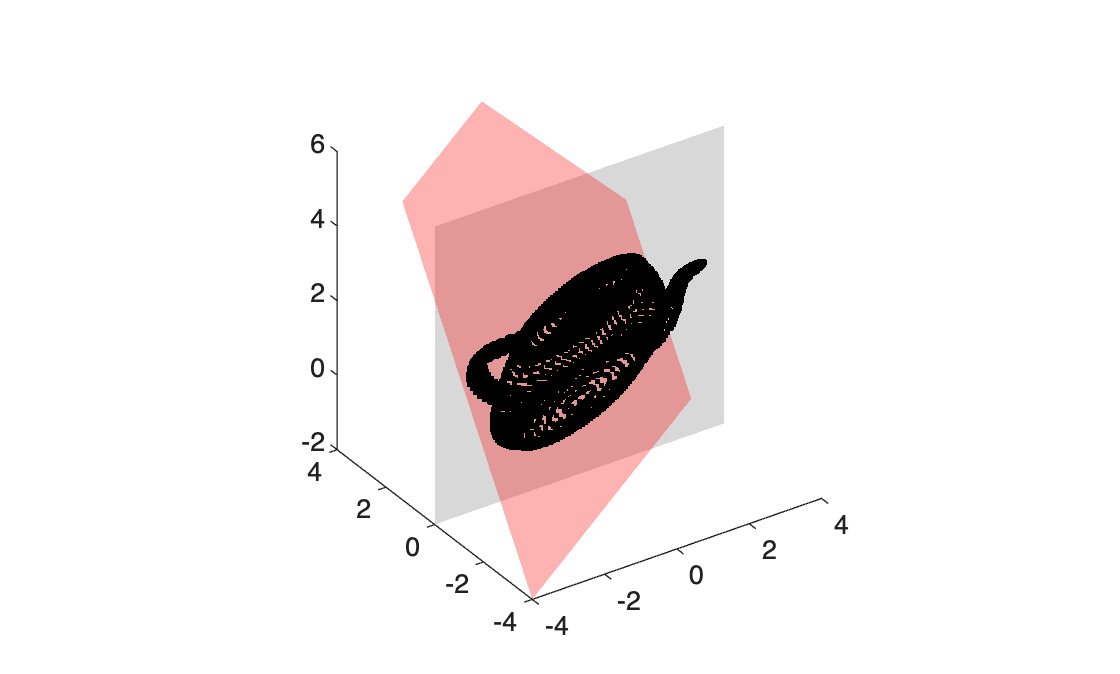

clear variables; close all; clc;
load('teapot.mat');
V = [1 0; 0 0; 0 1];
n = null(V');
W = 1/3*[2 1; 2 2; 1 2];
Pob = V*((W'*V)\W');
nfiber = null(W');
PobM = Pob*M;
constantplane(n,0)
hold on
constantplane(nfiber,0,'FaceColor','r')
% scatter3(M(1,:),M(2,:),M(3,:),'.')
scatter3(PobM(1,:),PobM(2,:),PobM(3,:),'k.')
axis equal, axis([-4,4,-4,4,-2,6])
hold off